**Rest API Show File**

%ip_url = 'https://10.64.68.210:5000';
ip_url = 'http://192.168.21.251:5000';
url = sprintf('%s/login', ip_url);
postData = struct('username', 'password', 'password', 'username'); % replace with actual values
options = weboptions('MediaType', 'application/json');
response = webwrite(url, postData, options);
headers = matlab.net.http.field.GenericField('Authorization', ['Bearer ' response.access_token]);
url = sprintf('%s/data', ip_url);
request = matlab.net.http.RequestMessage('GET', headers);
response = send(request, url);
data = response.Body.Data;
size_data = size(data);
for i = 1:size_data(1)
    disp(data(i))
end

         x_id: '6736ee12dce3710153a9a8a9'
    file_name: '20241115_133919.wav'

         x_id: '6736ee18dce3710153a9a8aa'
    file_name: 'Day2.wav'

         x_id: '6736ee5bdce3710153a9a8ad'
    file_name: 'net.onnx'

         x_id: '6736ef2edce3710153a9a8b0'
    file_name: 'net.onnx'

         x_id: '6736ef3cdce3710153a9a8b3'
    file_name: 'net.onnx'

         x_id: '6736ef3ddce3710153a9a8b6'
    file_name: 'net.onnx'

         x_id: '6736f4c9bc325b8edad149d2'
    file_name: '20241115_134414.wav'

         x_id: '6736f4cabc325b8edad149d3'
    file_name: '20241115_134510.wav'

         x_id: '6736f4cabc325b8edad149d4'
    file_name: '20241115_134538.wav'

         x_id: '6736f4cabc325b8edad149d5'
    file_name: '20241115_134514.wav'

         x_id: '6736f4cabc325b8edad149d6'
    file_name: '20241115_134407.wav'

         x_id: '6736f4cabc325b8edad149d7'
    file_name: '20241115_094152_punch_start.wav'

         x_id: '6736f4cabc325b8edad149d8'
    file_name: '20241115_134537.wav'

   

**Download File**

url = sprintf('%s/login', ip_url);
postData = struct('username', 'password', 'password', 'username'); % replace with actual values
options = weboptions('MediaType', 'application/json');
response = webwrite(url, postData, options);
headers = matlab.net.http.field.GenericField('Authorization', ['Bearer ' response.access_token]);

% Loop over each file entry in 'data' variable
for i = 1:length(data)
    filename = data(i).file_name;
    url = sprintf('%s/data/search?file_name=%s', ip_url, filename);
    
    % Send GET request
    request = matlab.net.http.RequestMessage('GET', headers);
    response = send(request, url);
    fileData = response.Body.Data;
    
    % Decode audio data
    audio_data = fileData.audio_data;
    decoded_audio = matlab.net.base64decode(audio_data);

    % Ensure the decoded data length is even
    if mod(length(decoded_audio), 2) ~= 0
        decoded_audio = decoded_audio(1:end-1);
    end

    % Convert byte data to audio samples
    audio_samples = typecast(decoded_audio, 'int16');
    num_channels = fileData.num_channels;
    num_frames = fileData.num_frames;

    % Check the sample length against expected frames and channels
    if length(audio_samples) ~= num_frames * num_channels
        warning('Decoded audio data does not match the expected number of frames and channels for file %s. Skipping this file.', filename);
        continue; % Skip to the next file
    end

    % Reshape audio samples to the appropriate format
    audio_samples = reshape(audio_samples, num_channels, num_frames).';

    % Save audio data to WAV file
    output_filename = sprintf('Source/%s', filename);
    audiowrite(output_filename, audio_samples, fileData.sample_rate);

    disp(['WAV file saved as ', output_filename]);
end

WAV file saved as Source/20241115_133919.wav
WAV file saved as Source/Day2.wav


Unrecognized method, property, or field 'audio_data' for class 'string'.

**Playback Sound**

filepath = "/home/entity014/TESA-2024/Matlab/Integration/Source/Day2.wav";
[samples, Fs] = audioread(filepath);

player = audioplayer(samples, Fs);
play(player);

**Stop Sound**

stop(player);

**Cut**

class = "Normal";
init_i = 0;
path = sprintf(filepath);
[audioData, Fs] = audioread(path);

shortWinLength = round(0.3 * Fs);
longWinLength = round(2.0 * Fs);

shortRMS = dsp.MovingRMS(shortWinLength);
longRMS = dsp.MovingRMS(longWinLength);

env1 = shortRMS(audioData);
env2 = longRMS(audioData);

shortOffset = round(shortWinLength/2);
longOffset = round(longWinLength/2);

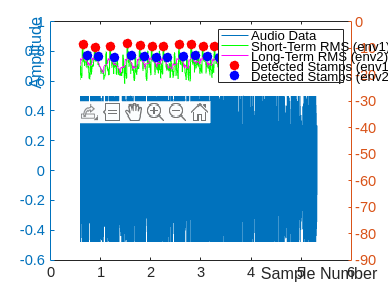

% Calculate thresholds for env1 and env2
threshold1 = mean(env1) + 1.99 * std(env1); % Adjust multiplier based on sensitivity
threshold2 = mean(env2) + 0.4 * std(env2);

% Find peaks above thresholds
[peaks1, locs1] = findpeaks(env1, 'MinPeakHeight', threshold1, 'MinPeakDistance', shortWinLength + 1e5);
[peaks2, locs2] = findpeaks(env2, 'MinPeakHeight', threshold2, 'MinPeakDistance', longWinLength + 6.9e4);

% Plot the audio data and envelope with detected events
figure;
yyaxis left;
plot(audioData);
ylabel('Amplitude');
hold on;

yyaxis right;
plot(mag2db(env1(shortOffset:end)), 'g-');
plot(mag2db(env2(longOffset:end)), 'm-');

% Mark detected peaks (stamping events)
yyaxis right;
plot(locs1, mag2db(peaks1), 'ro', 'MarkerFaceColor', 'r'); % Stamps detected by env1
plot(locs2, mag2db(peaks2), 'bo', 'MarkerFaceColor', 'b'); % Stamps detected by env2

legend('Audio Data', 'Short-Term RMS (env1)', 'Long-Term RMS (env2)', 'Detected Stamps (env1)', 'Detected Stamps (env2)');
title('Stamping Event Detection');
xlabel('Sample Number');
ylabel('RMS (dB)');
hold off;

size_file = size(locs1);
for i = 1:size_file(1)

        filename = sprintf("Train/%s/%s%d.wav",class, class, init_i + i);  % Use %d to insert the loop index
        % Write the audio data to the WAV file
        audiowrite(filename, audioData(locs1(i) - 1.2e4:locs2(i)), Fs);
end

**Test Sound**

player = audioplayer(audioData(locs(1) - 1e4:locs(1) + 1e4), Fs); % must specify correct sampling rate
play(player);